clear all; clc; close all
load exhaustive_MTA3.mat
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(0, 'DefaultAxesFontSize', 22);
s = 1;
[comparison_table, idx] = sortrows(comparison_table,2,'descend');
Jt = (Translation+s*Variance_t)./Length;
Jt = Jt(idx);

Jr = (abs(Rotation)+s*Variance_theta)./Length;
Jr = Jr(idx);
opt_t = {[3,6]; [1,8,2]; [1,6,4,5,7]}

opt_t = 3×1 cell array
    {[      3 6]}
    {[    1 8 2]}
    {[1 6 4 5 7]}


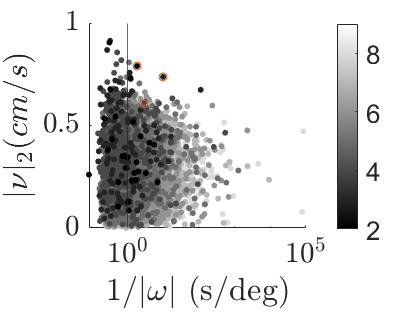

opt_t2 = {[1,3];[4,5,6,7];[3,8,5];[1,4,7,5,8,3];[3,5];[1,4,7,5,3]};
for i = 1:length(opt_t)
    cell_t = repmat(opt_t{i},length(Sequence),1);
    cell_t = num2cell(cell_t,2);
    idx_t(i) = find(cellfun(@isequal, comparison_table.Sequence, cell_t));
end
opt_theta = {[1,4,2], [1,3,4,2,6,7], [1,7,5,6,2,4]};
for i = 1:length(opt_theta)
    cell_t = repmat(opt_theta{i},length(Sequence),1);
    cell_t = num2cell(cell_t,2);
    idx_theta(i) = find(cellfun(@isequal, comparison_table.Sequence, cell_t));
end

figure
c = comparison_table.Length;
ex_plot = scatter(1./comparison_table.Rot_Speed, comparison_table.Linear_Speed,20,c,'filled');

hold on
scatter(1./comparison_table.Rot_Speed(idx_t), comparison_table.Linear_Speed(idx_t))
colormap(gray)
a = colorbar;
set(gca,'CLim',[2 9]);
xline(1)
set(gca,'xscale','log')
xlabel('$1/|\omega|$ (s/deg)','Interpreter','latex')
ylabel('$|\nu|_2 (cm/s)$','Interpreter','latex')

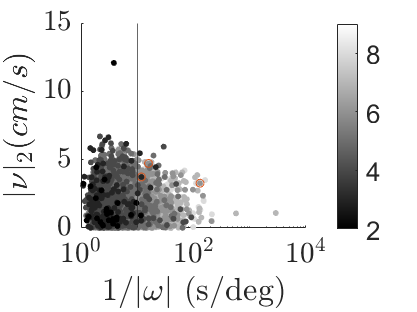


figure
c = comparison_table.Length;
ex_plot = scatter(1./comparison_table.Linear_Speed, comparison_table.Rot_Speed,20,c,'filled');

hold on
scatter(1./comparison_table.Linear_Speed(idx_theta), comparison_table.Rot_Speed(idx_theta))
colormap(gray)
a = colorbar;
set(gca,'CLim',[2 9]);
xline(2/.2)
set(gca,'xscale','log')
xlabel('$1/|\omega|$ (s/deg)','Interpreter','latex')
ylabel('$|\nu|_2 (cm/s)$','Interpreter','latex')

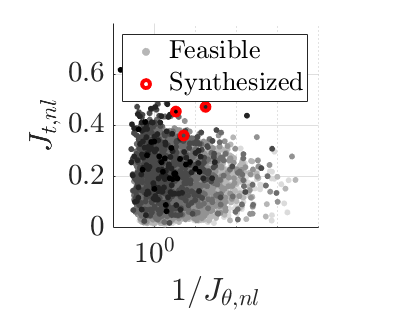


figure
c = comparison_table.Length;
ex_plot = scatter(1./Jr, Jt,20,c,'filled');
set(gca,'xscale','log')
exp_plot.Marker = '.';
colormap(gray)
%a = colorbar;
%a.Location = 'northoutside';
%a.Label.String = 'Gait Length';
set(gca,'CLim',[2 9]);
hold on
scatter(1./Jr(idx_t), Jt(idx_t),35,'r','LineWidth',3)
xlim([10^(-1),10^4])
%yticks([.1 1 10 100 1000 10000])
%yticklabels({'$10^{-1}$', '$10^{0}$', '$10^{1}$', '$10^{2}$', '$10^{3}$', '$10^{4}$'} )
ylim([0 0.8])
xlabel('$1/J_{\theta,nl}$','Interpreter','latex')
ylabel('$J_{t,nl}$','Interpreter','latex')
grid on
legend('Feasible','Synthesized','Interpreter','latex')
pbaspect([4 4 1])

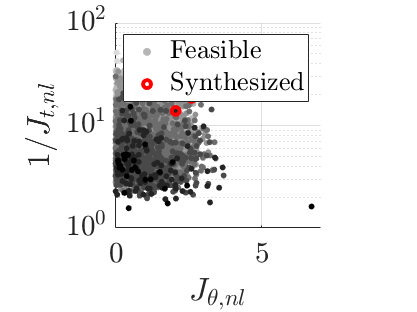



figure
c = comparison_table.Length;
ex_plot = scatter(Jr,1./Jt,20,c,'filled');
set(gca,'yscale','log')
exp_plot.Marker = '.';

colormap(gray)
%a = colorbar;
%a.Location = 'northoutside';
%a.Label.String = 'Gait Length';
set(gca,'CLim',[2 9]);
hold on
scatter( Jr(idx_theta),1./Jt(idx_theta),35,'r','LineWidth',3)
xlim([0 7])
ylim([1 10^2])
grid on
xlabel('$J_{\theta,nl}$','Interpreter','latex')
ylabel('$1/J_{t,nl}$','Interpreter','latex')
legend('Feasible','Synthesized','Interpreter','latex')
pbaspect([4 4 1])